# Digital Signal Processing Homework 3

## Syed Asghar Abbas Zaidi and Daniyal Rahim

This is an open-ended group assignment (2 members maximum) to  design standard bandpass filters with bandpass frequency 𝜔𝑜 = 𝜋/𝐴, where A is pi/7 to you in the groups on LMS. 

The specifications are as follows:

- The bandwidth ∆𝜔 of the notch filter should be at most 0.02. The bandwidth is the  range of frequencies over which the filter's gain is within 3 dB (or 70.7%) of its  maximum gain, in radians, around the null frequency. 

-  The passband ripple may be 0.01 at most and stop band ripple be 0.02.  

Also note the following additional instructions:

- As this is an open-ended assignment, you are free to use any and all resources  available to you online or offline, especially MATLAB. But your submission will  require references for any information which isn’t your own.

- Be as accurate as possible to the required specifications.

- Share all relevant diagrams (including magnitude, phase and z- transform plots) in your submission.

- You may be asked to justify your design with a viva.

- It should not take you more than 8 hours to complete this assignment. 

## Part (a)

### Design an IIR bandpass filter using eitther pole-zero placement, bilinear  transformation or any other approximation method of your choice, complete with difference equation and implementation.

% pass band and stop band edges, divided by pi
%Wp = [Wpl Wpu]/pi and Ws = [Wsl Wsu]/pi;
wp = [0.438799 0.458799]/pi;
ws = [0.34879895 0.54879895]/pi;
Ap = 3;
As = 34.0658;
[N wc] = buttord(wp, ws, Ap, As) %Get cutoff and order

N = 2

wc =     0.1388    0.1470


ww = tan(wc.*pi/2)% value of cutoff in analog equivalent

ww =     0.2215    0.2351


[z, p] = butter(N, wc, 'bandpass')% get filter coefficients

z = 1.0e-03 *

    0.1637         0   -0.3274         0    0.1637


p =     1.0000   -3.5712    5.1520   -3.5065    0.9641


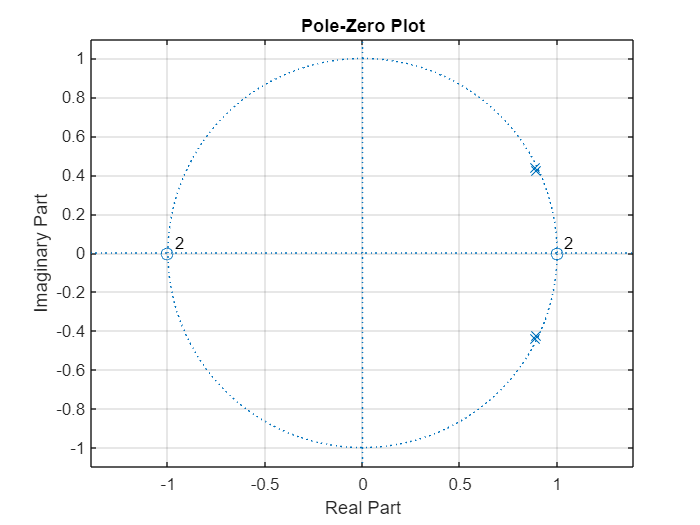

zplane(z, p);grid on;

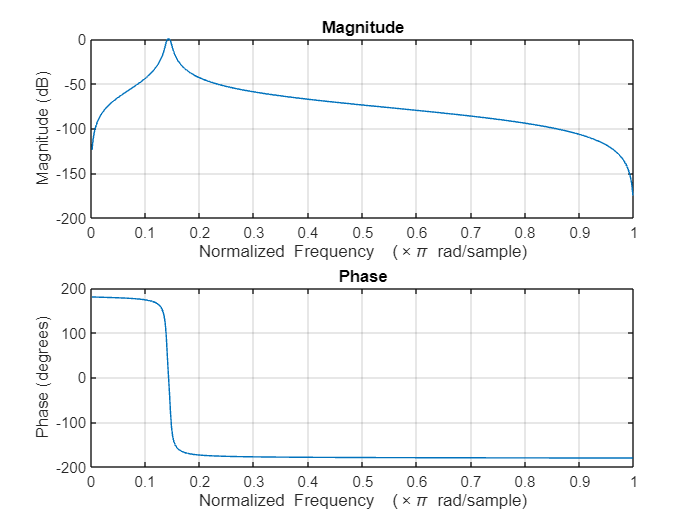

freqz(z, p);

%Zeroz = [0.013584 , -0.013584];
%Poles = [1.016295, -1.010873];
%zplane(Zeroz, Poles);
%grid on;
%figure;
%freqz(Zeroz, Poles);

### B) Design a FIR bandpass filter with linear phase, complete with difference equation and implementation. 

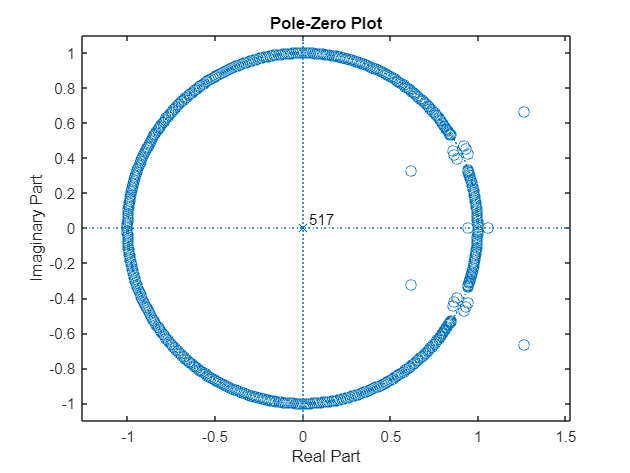

Wo = pi/7; %This is radians/sample (Digital Frequency)
D_s = 0.02; %Stopband Ripples
D_p = 0.01; %Passband Ripples
Bandwidth = 0.02;
M = 518; 
N = M - 1; %Order (N) = Length (M) - 1;
t_freq = 0.1;
%We will be using the Parks_McClellan algorithm to design the filter! 
Parks_Algo = firpm(N, [0, Wo-(Bandwidth/2)-t_freq, Wo-(Bandwidth/2), Wo+(Bandwidth/2),Wo+(Bandwidth/2)+t_freq,pi]/pi, [0, 0, 1, 1, 0, 0]);
zplane(Parks_Algo,1);

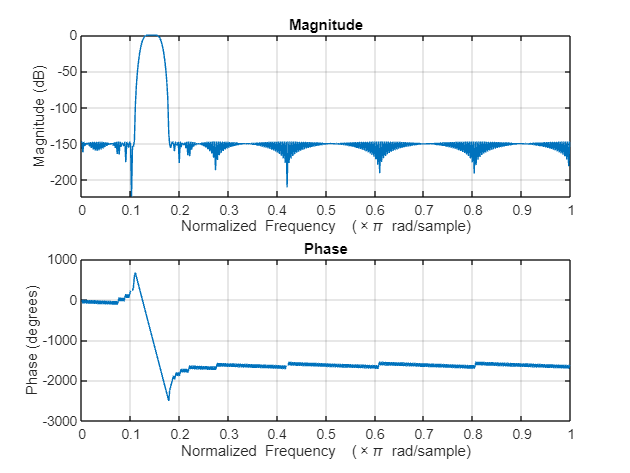

%This will plot the frequency response 
freqz(Parks_Algo,1)  

#### Analysis:

The MATLAB code provided designs a finite impulse response (FIR) filter using the Parks-McClellan algorithm. This algorithm is employed to meet specific frequency response requirements, such as passband and stopband ripples. The code initializes parameters defining the filter's characteristics, calculates the filter order, and designs the filter using the **firpm** function. Visualization tools (zplane and freqz) are then utilized to analyze the filter's stability and frequency response. Overall, the code demonstrates the process of designing an FIR filter with precise frequency response specifications in MATLAB.

The **firpm** function in MATLAB is utilized for designing finite impulse response (FIR) filters. It employs the Parks-McClellan algorithm, aiming to approximate the desired frequency response with minimal error. Users provide input parameters including the filter order, frequency band edges, and desired magnitude response. **firpm** then optimizes filter coefficients to minimize error between the desired and actual frequency responses.

### C) Design a FIR filter using a windowing function of your choice to truncate  the time domain function of an ideal bandpass filter, complete with difference equation and  implementation.

Wo = pi/7; %This is radians/sample (Digital Frequency)
D_s = 0.02; %Stopband Ripples
D_p = 0.01; %Passband Ripples
Bandwidth = 0.02;
M = 1037;
N = M-1;
%Using the Hamming window method to design the filter
Hamming_Algo = fir1(N, [Wo-Bandwidth/2, Wo+Bandwidth/2]/pi, 'bandpass', hamming(M));
disp(Hamming_Algo);

   -0.0001   -0.0001   -0.0001   -0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000    0.0000    0.0001    0.0001    0.0002    0.0001    0.0001    0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0001   -0.0000    0.0000    0.0001    0.0002    0.0002    0.0002    0.0001    0.0000   -0.0000   -0.0001   -0.0002   -0.0002   -0.0002   -0.0001   -0.0000    0.0000    0.0001    0.0002    0.0002    0.0002    0.0001    0.0000   -0.0000   -0.0001   -0.0002   -0.0002   -0.0002

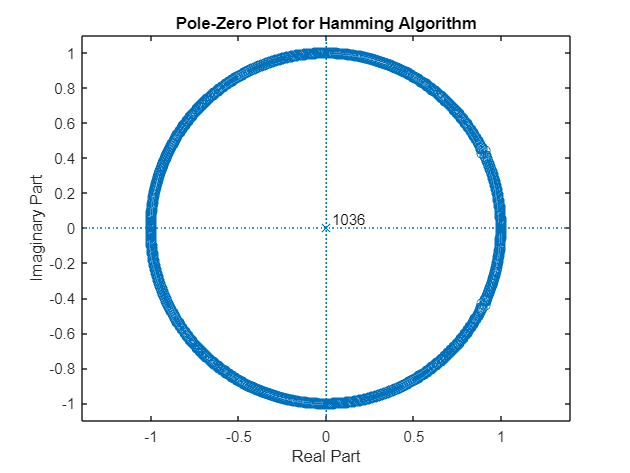

 zplane(Hamming_Algo, 1); title('Pole-Zero Plot for Hamming Algorithm');

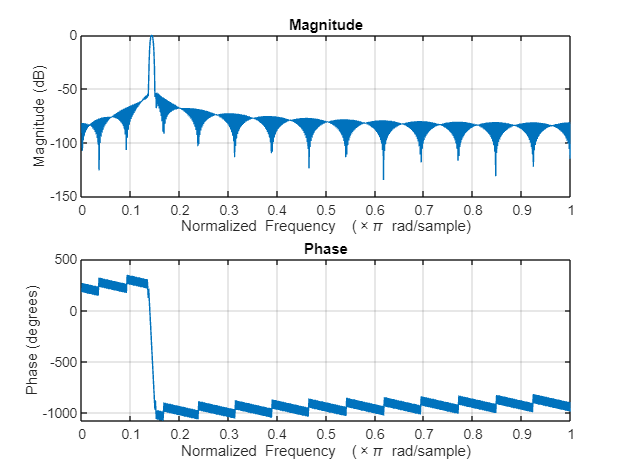

freqz(Hamming_Algo, 1, 1024); %This plots the frequency response